clear variables;
addpath('fcts\')

## Chapter 1

page 15: Genetic Algorithms at work

M = 200; %mRows
N = 10; %nColumns

CONVERGENCE_MAGNITUDE = 6;

till convergence:

parentalGenepool = create_mat_of_random_logical(N,M);

%initialization
i_Generation = 1;
averageFitnessArray(i_Generation) = 1;
percentFitness = 0;

childGenepool = parentalGenepool;
while percentFitness ~= 1
    i_Generation = i_Generation + 1;
    valueArray = convert_array_of_logicals_2_nums(childGenepool);

    yArray = (valueArray.^2);    %fitness fuction
    averageFitnessArray(i_Generation) = sum(yArray)/M;

    probabilityArray = yArray/sum(yArray);

    eventsRoulette = simulate_n_roulettespins(probabilityArray, M);
    childGenepool = create_crossing_over(create_mating_genepool(childGenepool,eventsRoulette));

    percentFitness = round(averageFitnessArray(i_Generation)/averageFitnessArray(i_Generation-1),CONVERGENCE_MAGNITUDE);
end

disp("original Genepool");disp(parentalGenepool);

original Genepool
     1     1     0     0     1     1     1     1     0     0     0     1     0     0     0     0     1     0     0     1     0     0     1     0     0     1     0     0     1     0     0     1     1     0     0     1     1     1     0     1     1     0     0     1     1     1     0     0     1     0     0     1     1     0     0     0     0     0     0     0     0     1     0     0     1     0     0     1     0     1     0     0     0     0     1     0     1     1     1     0     1     0     0     0     1     1     0     1     0     0     0     1     0     0     1     0     0     0     0     1     1     1     0     0     1     1     1     1     1     0     1     0     1     0     1     1     0     1     1     0     1     0     1     0     0     0     0     0     1     0     1     0     1     1     0     1     0     1     0     1     0     1     1     1     1     0     0     0     0     0     0     0     0     1     0     1     1     0     1     1     0     0     1    

disp("converged Genepool");disp(childGenepool);

converged Genepool
   0   1   0   1   1   1   1   1   1   1   1   1   0   1   0   0   1   1   0   0   1   1   0   0   1   1   1   1   1   1   0   1   0   1   0   1   0   1   1   0   0   0   1   0   1   0   0   0   1   1   0   0   0   1   0   0   0   1   0   1   1   1   0   0   0   1   0   0   0   0   1   1   1   0   1   1   1   0   1   0   1   1   0   0   1   0   1   0   0   1   1   0   1   1   1   1   0   0   0   1   1   1   0   1   1   1   0   0   1   0   0   0   1   1   0   1   1   1   1   0   0   1   1   1   1   1   1   1   1   1   1   0   1   0   0   1   1   1   1   1   1   1   1   0   0   1   1   0   0   1   1   1   1   1   0   0   1   0   1   1   1   1   0   1   0   1   1   1   1   0   1   1   1   1   1   0   0   1   1   1   0   0   0   1   1   1   0   0   0   0   0   0   1   1   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1

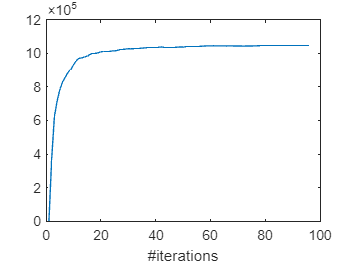

plot((1:i_Generation),averageFitnessArray);xlabel("#iterations")